# **Assignment:  Feature Extraction of CWRU Dataset**

**Name: MinungHan**

**Given:  ****CWRU bearing dataset (bearing open data set)**

[https://engineering.case.edu/bearingdatacenter/download-data-file](https://engineering.case.edu/bearingdatacenter/download-data-file)

Classes:

-  Normal / Outer Race fault / Inner Race fault / Ball fault

**Instruction**

This Assignment is implementation a part of Feature Extration in  the literature 

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**1. Extract and Analyze  Features**

**2. Compare  Features among different classes**

- **3가지 센서에 대해 서로 다른 데이터가 들어온다.**

- **주로, 베어링과 제일 가까운 DE data를 많이 사용할 것이다.**

## Dataset

Sampling: 

- **Drive end bearing(12K): 12,000 samples/second**

Classes:

- Normal / Outer Race fault / Inner Race fault

- Each under 1HP load,  fault diameter of 0.007inches

Variables

- DE - drive end accelerometer data

- FE - fan end accelerometer data

- BA - base accelerometer data

- time - time series data

- RPM - shaft rpm during testing

### Drive End Bearing Experiment- 12K

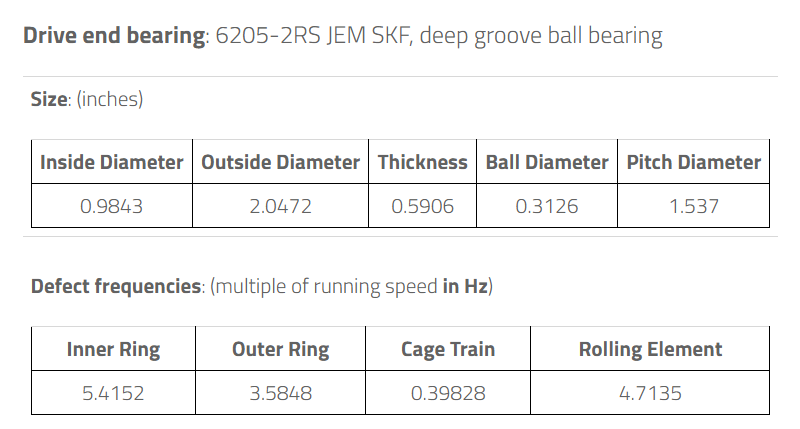

## **Analyze Features **

• Extract Time-Domain Features

• Extract Frequency-Domain Features

• Plot  STFT 

• Envelop Extraction

• Plot  Kurtogram

• Analyze Spectral Kurtosis

## **1. Data load**

- Normal data = X098

- Inner crack  = X106

- Ball bearing = X119

- Outer crack = X131

clc; clear all; close all;
% DE - drive end accelerometer data
% FE - fan end accelerometerd
% BA - base accelerometer data

addpath('../Bearingdata');
addpath('../../Functions');

load('ball_007_1hp.mat');
load('inner_007_1hp.mat');
load('normal_1hp.mat');
load('outer_007_1hp.mat');


% Variabke declaration
Fs = 12000;     % [Hz]

Len = struct('X098', length(X098_FE_time), ...
             'X106', length(X106_FE_time), ...
             'X119', length(X119_FE_time), ...
             'X131', length(X131_FE_time) );

Time_features = struct('X098_DE', timeFeatures(X098_DE_time), ...
                       'X098_FE', timeFeatures(X098_FE_time), ...
                       'X106_BA', timeFeatures(X106_BA_time), ...
                       'X106_DE', timeFeatures(X106_DE_time), ...
                       'X106_FE', timeFeatures(X106_FE_time), ...
                       'X119_BA', timeFeatures(X119_BA_time), ...
                       'X119_DE', timeFeatures(X119_DE_time), ...
                       'X119_FE', timeFeatures(X119_FE_time), ...
                       'X131_BA', timeFeatures(X131_BA_time), ...
                       'X131_DE', timeFeatures(X131_DE_time), ...
                       'X131_FE', timeFeatures(X131_FE_time) );

Freq_features = struct('X098_DE', freqFeatures(X098_DE_time), ...
                       'X098_FE', freqFeatures(X098_FE_time), ...
                       'X106_BA', freqFeatures(X106_BA_time), ...
                       'X106_DE', freqFeatures(X106_DE_time), ...
                       'X106_FE', freqFeatures(X106_FE_time), ...
                       'X119_BA', freqFeatures(X119_BA_time), ...
                       'X119_DE', freqFeatures(X119_DE_time), ...
                       'X119_FE', freqFeatures(X119_FE_time), ...
                       'X131_BA', freqFeatures(X131_BA_time), ...
                       'X131_DE', freqFeatures(X131_DE_time), ...
                       'X131_FE', freqFeatures(X131_FE_time) );

Flen = struct('X098_DE', Fs * (0:(Len.X098/2))/Len.X098, ...
           'X098_FE', Fs * (0:(Len.X098/2))/Len.X098, ...
           'X106_BA', Fs * (0:(Len.X106/2))/Len.X106, ...
           'X106_DE', Fs * (0:(Len.X106/2))/Len.X106, ...
           'X106_FE', Fs * (0:(Len.X106/2))/Len.X106, ...
           'X119_BA', Fs * (0:(Len.X119/2))/Len.X119, ...
           'X119_DE', Fs * (0:(Len.X119/2))/Len.X119, ...
           'X119_FE', Fs * (0:(Len.X119/2))/Len.X119, ...
           'X131_BA', Fs * (0:(Len.X131/2))/Len.X131, ...
           'X131_DE', Fs * (0:(Len.X131/2))/Len.X131, ...
           'X131_FE', Fs * (0:(Len.X131/2))/Len.X131 );

FFT = struct('X098_DE', getFFT(X098_DE_time, Len.X098), ...
             'X098_FE', getFFT(X098_FE_time, Len.X098), ...
             'X106_BA', getFFT(X106_BA_time, Len.X106), ...
             'X106_DE', getFFT(X106_DE_time, Len.X106), ...
             'X106_FE', getFFT(X106_FE_time, Len.X106), ...
             'X119_BA', getFFT(X119_BA_time, Len.X119), ...
             'X119_DE', getFFT(X119_DE_time, Len.X119), ...
             'X119_FE', getFFT(X119_FE_time, Len.X119), ...
             'X131_BA', getFFT(X131_BA_time, Len.X131), ...
             'X131_DE', getFFT(X131_DE_time, Len.X131), ...
             'X131_FE', getFFT(X131_FE_time, Len.X131) );

## 2. Normal data

2-1. Signal form

We need to calculate the time considering data size and the sampling frequency.

After that, we can plot of the normal data.

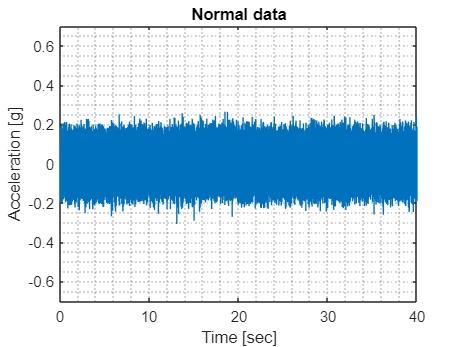

figure

time_norm = (0 : Len.X098 - 1)/Fs;

plot(time_norm, X098_DE_time');

xlabel("Time [sec]");   ylabel("Acceleration [g]");   grid minor;   title("Normal data");        
xlim([0 40]);   ylim([-0.7 0.7]);

2-2. Time-feature of normal data

- Based on the time features of normal data, we can refer the datas and set the critical point for fault diagnosis.

time_X098 = timeFeatures(X098_DE_time);
time_X098;

2-3. FFT  / Frequency-features

- Based on the frequency features of normal data, we can refer the datas and set the critical point for fault diagnosis.

- Based on the FFT result of normal data, it is possible to know which frequency is dominant in the normal system.

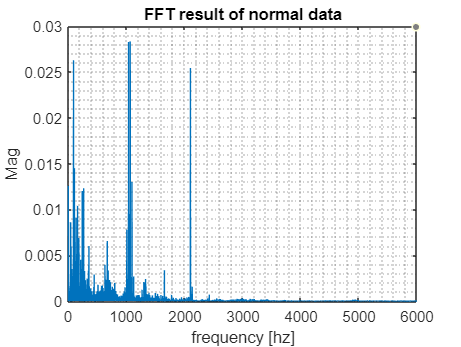

figure()
plot(Flen.X098_DE, FFT.X098_DE);
xlabel("frequency [hz]");   ylabel("Mag");  title("FFT result of normal data"); grid minor;


freq_X098 = freqFeatures(X098_DE_time);

2-4. STFT

- STFT for frequency varying signal

- Through this procedure, we can observe specific frequency signal of normal data

- In the normal data, it can be seen that a constant frequency gain is maintained over time.

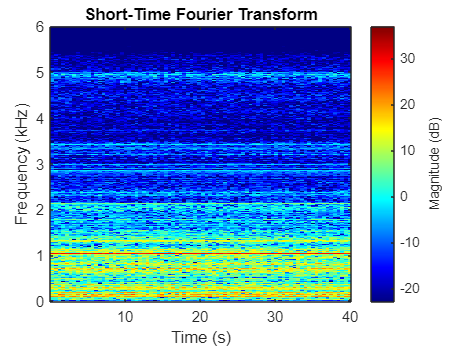

figure()
stft(X098_DE_time, Fs, 'Window', hamming(6000,'periodic'), 'OverlapLength', 128,'FrequencyRange','onesided');
colormap jet

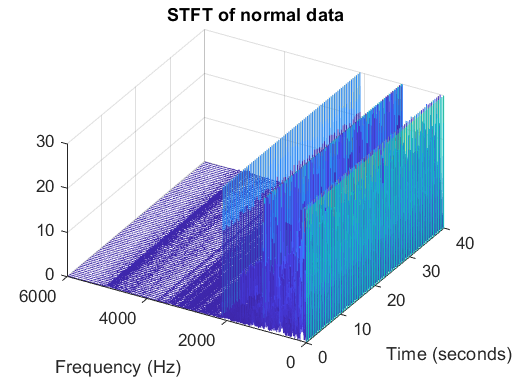


figure()
[S,F,T] = stft(X098_DE_time,Fs, 'Window', hamming(6000,'periodic'), "OverlapLength", 128,'FrequencyRange','onesided');
waterfall(F,T,abs(S)');
helperGraphicsOpt(1);
title("STFT of normal data");

## 3. Inner crack data

3-1. Signal form

We need to calculate the time considering data size and the sampling frequency.

After that, we can plot of the inner crack data.

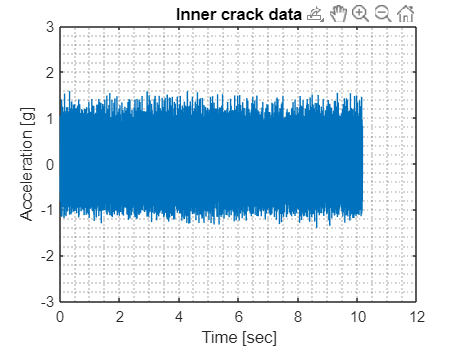

figure()

time_inner = (0 : Len.X106 - 1)/Fs;

plot(time_inner, X106_DE_time');

xlabel("Time [sec]");   ylabel("Acceleration [g]");   grid minor;   title("Inner crack data");        
xlim([0 12]);   ylim([-3 3]);

3-2. Time-feature of inner crack data

time_X106 = timeFeatures(X106_DE_time);
time_X106;

3-3. FFT  / Frequency-features

- Based on the frequency features of normal data, we can refer the datas and set the critical point for fault diagnosis.

- As we can see in the FFT result, multiple signals of different frequencies are observed.

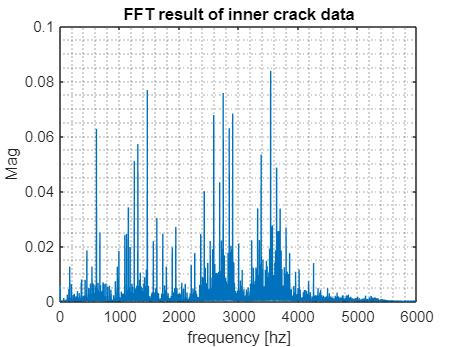

figure()
plot(Flen.X106_DE, FFT.X106_DE);
xlabel("frequency [hz]");   ylabel("Mag");  title("FFT result of inner crack data"); grid minor;


freq_X106 = freqFeatures(X098_DE_time);

3-4. STFT

- STFT for frequency varying signal

- In the inner crack data, it can be seen that a multiple signals with different frequencies are appeared.

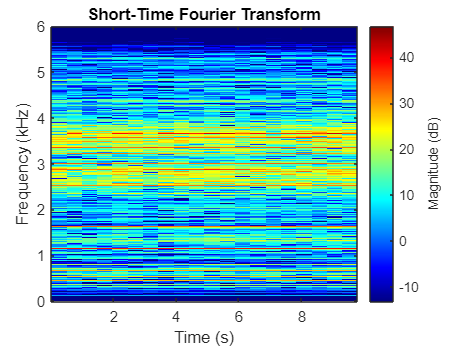

figure()
stft(X106_DE_time, Fs, 'Window', hamming(6000,'periodic'), 'OverlapLength', 128,'FrequencyRange','onesided');
colormap jet

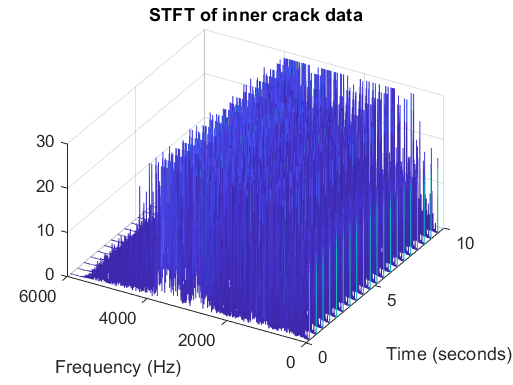


figure()
[S,F,T] = stft(X106_DE_time,Fs, 'Window', hamming(6000,'periodic'), "OverlapLength", 128,'FrequencyRange','onesided');
waterfall(F,T,abs(S)');
helperGraphicsOpt(1);
title("STFT of inner crack data");

## 4. Outer crack data

4-1. Signal form

We need to calculate the time considering data size and the sampling frequency.

After that, we can plot of the outer crack data.

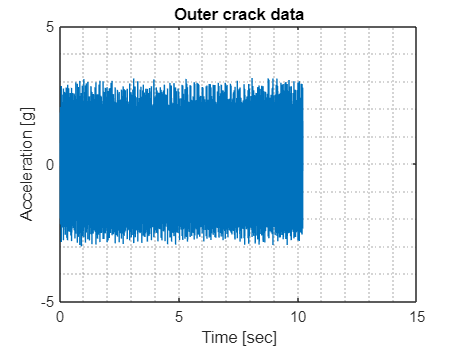

figure

time_outer = (0 : Len.X131 - 1)/Fs;

plot(time_outer, X131_DE_time');

xlabel("Time [sec]");   ylabel("Acceleration [g]");   grid minor;   title("Outer crack data");        
xlim([0 15]);   ylim([-5 5]);

4-2. Time-feature of outer cracked data

time_X131 = timeFeatures(X131_DE_time);
time_X131;

4-3. FFT  / Frequency-features

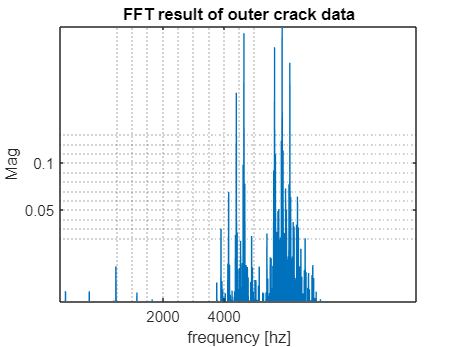

figure()
plot(Flen.X131_DE, FFT.X131_DE);
xlabel("frequency [hz]");   ylabel("Mag");  title("FFT result of outer crack data"); grid minor;


freq_X131 = freqFeatures(X131_DE_time);

4-4. STFT

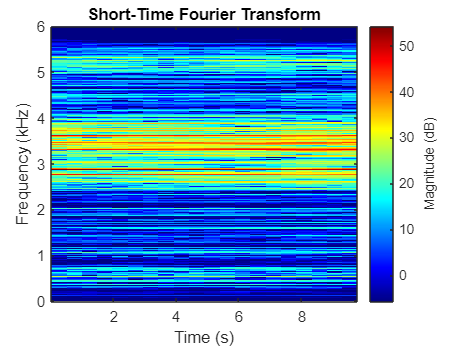

figure()
stft(X131_DE_time, Fs, 'Window', hamming(6000,'periodic'), 'OverlapLength', 128,'FrequencyRange','onesided');
colormap jet

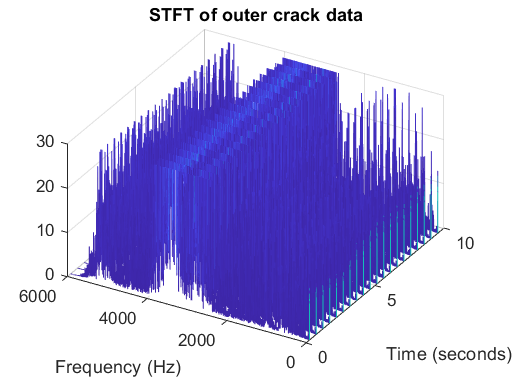


figure()
[S,F,T] = stft(X131_DE_time,Fs, 'Window', hamming(6000,'periodic'), "OverlapLength", 128,'FrequencyRange','onesided');
waterfall(F,T,abs(S)');
helperGraphicsOpt(1);
title("STFT of outer crack data");

## 5. Ball fault data

5-1. Signal form

We need to calculate the time considering data size and the sampling frequency.

After that, we can plot of the ball fault data.

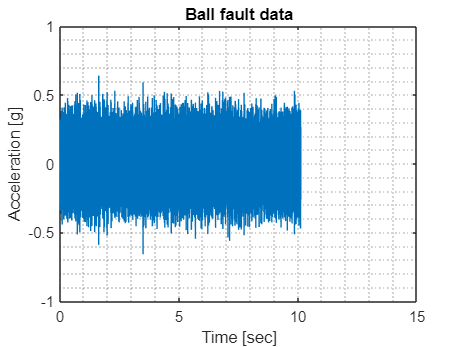

figure

time_ball = (0 : Len.X119 - 1)/Fs;

plot(time_ball, X119_DE_time');

xlabel("Time [sec]");   ylabel("Acceleration [g]");   grid minor;   title("Ball fault data");        
xlim([0 15]);   ylim([-1 1]);

5-2. Time-feature of ball fault data

time_X119 = timeFeatures(X119_DE_time);
time_X119;

5-3. FFT  / Frequency-features

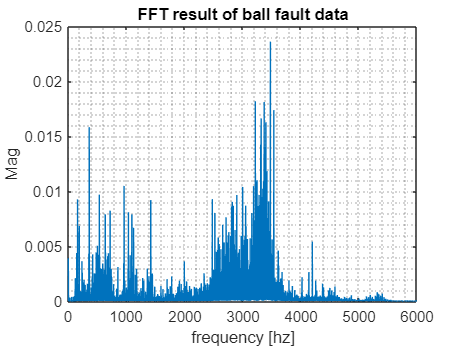

figure()
plot(Flen.X119_DE, FFT.X119_DE);
xlabel("frequency [hz]");   ylabel("Mag");  title("FFT result of ball fault data"); grid minor;

freq_X119 = freqFeatures(X119_DE_time);

5-4. STFT

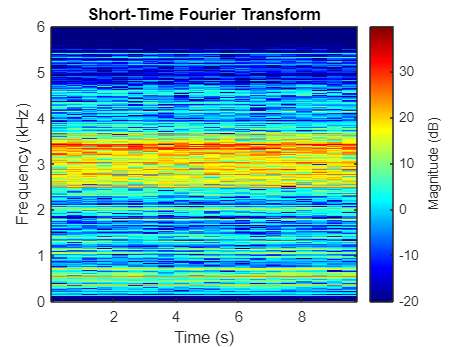

figure()
stft(X119_DE_time, Fs, 'Window', hamming(6000,'periodic'), 'OverlapLength', 128,'FrequencyRange','onesided');
colormap jet

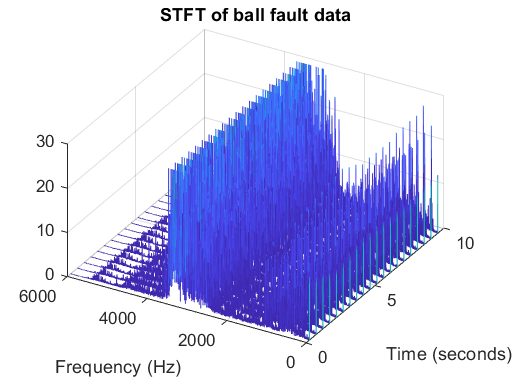


figure()
[S,F,T] = stft(X119_DE_time,Fs, 'Window', hamming(6000,'periodic'), "OverlapLength", 128,'FrequencyRange','onesided');
waterfall(F,T,abs(S)');
helperGraphicsOpt(1);
title("STFT of ball fault data");